## Regularization

Q:What is **Regularization**?

A: **Regularization** is a technique that **prevents the model from overfitting **on the data by adding a penalty to the weights of model.

Q: What types of regularization exists?

A: There are **3 **main types of **regularization:**

- **Lasso **or **L1 norm**

- **Ridge **or **L2 norm**

- **Dropout**, which we will see in **Deep learning.**

load carbig
feature_units = ["ms/" "tons" "lt" "HP"];
feature_names = ["Acceleration" "Weight" "Displacement" "Horsepower"];
X = [Acceleration Weight Displacement Horsepower];
y = MPG;


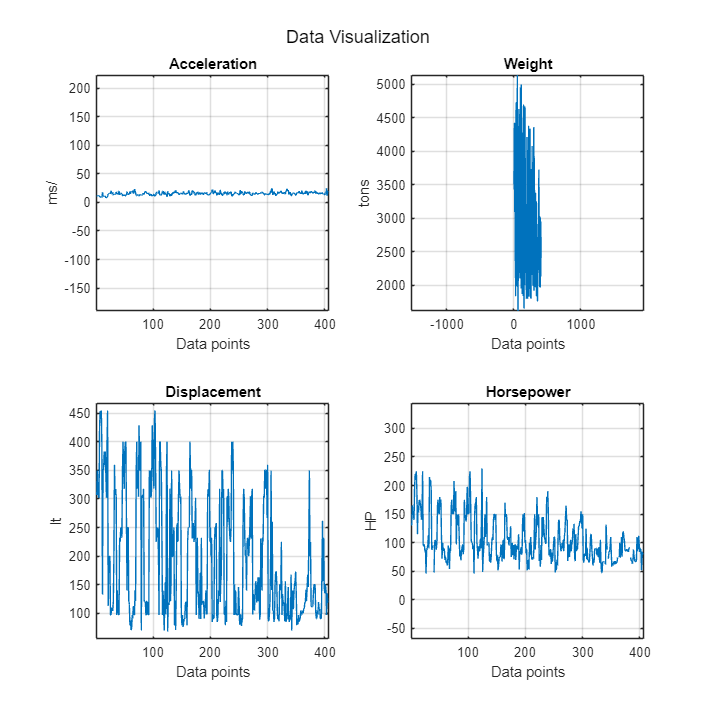

% Visualize the data 
f = figure;
f.Position(3:4) = [1080, 1080];
%f.set
sgtitle("Data Visualization")

for feature=1:4
    
    subplot(2, 2, feature)
    p=plot(X(:,feature));
    axis equal
    title(feature_names(feature))
    grid on
    p.DisplayName = feature_names(feature);
    xlabel("Data points")
    
    ylabel(feature_units(feature))
end

n = length(y);
rng('default') % For reproducibility
c = cvpartition(n,'HoldOut',0.3);
idxTrain = training(c, 1);
idxTest = ~idxTrain;

bias_term = ones(size(X,1),1);
X_with_bias = cat(2,bias_term,X)

X_with_bias = 1.0e+03 *

    0.0010    0.0120    3.5040    0.3070    0.1300
    0.0010    0.0115    3.6930    0.3500    0.1650
    0.0010    0.0110    3.4360    0.3180    0.1500
    0.0010    0.0120    3.4330    0.3040    0.1500
    0.0010    0.0105    3.4490    0.3020    0.1400
    0.0010    0.0100    4.3410    0.4290    0.1980
    0.0010    0.0090    4.3540    0.4540    0.2200
    0.0010    0.0085    4.3120    0.4400    0.2150
    0.0010    0.0100    4.4250    0.4550    0.2250
    0.0010    0.0085    3.8500    0.3900    0.1900


b = regress(y(1:300), X_with_bias(1:300,:));

disp("The siple multi-regression coefs are:")

The siple multi-regression coefs are:


disp(b')

   40.4650   -0.0812   -0.0047   -0.0071   -0.0215



y_multi_hat = X_with_bias(1:300,:) * b;
[error, error_std] = rmse(y(1:300), y_multi_hat);

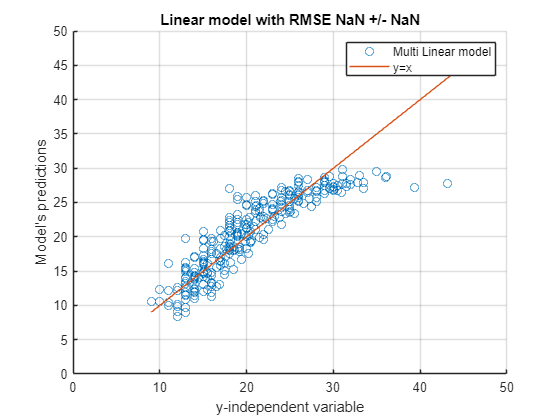

x_line = min(y):max(y);
figure
hold on
scatter(y(1:300), y_multi_hat, DisplayName="Multi Linear model")
plot(x_line, x_line, DisplayName="y=x")
grid on
xlabel('y-independent variable')
ylabel("Model's predictions")
legend()
title_text = sprintf("Linear model with RMSE %0.3f +/- %0.2f", error, error_std );
title(title_text);
xlim([0, 50])
ylim([0, 50])

k = 5;
ridge_b = ridge(y(1:300), X(1:300,:), k, 0);
disp("The ridge multi-regression coefs are:")

The ridge multi-regression coefs are:


disp(ridge_b')

   40.3240   -0.1018   -0.0043   -0.0094   -0.0239



y_ridge_hat = ridge_b(1) + X(1:300,:) *ridge_b(2:end);

y_ridge_hat

y_ridge_hat =    18.1077
   16.0890
   17.9018
   17.9472
   18.3012
   11.9421
   11.2095
   11.6981
   10.6745
   14.7407


y(1:300)

ans =     18
    15
    18
    16
    17
    15
    14
    14
    14
    15


[error, error_std] = rmse(y(1:300), y_ridge_hat);

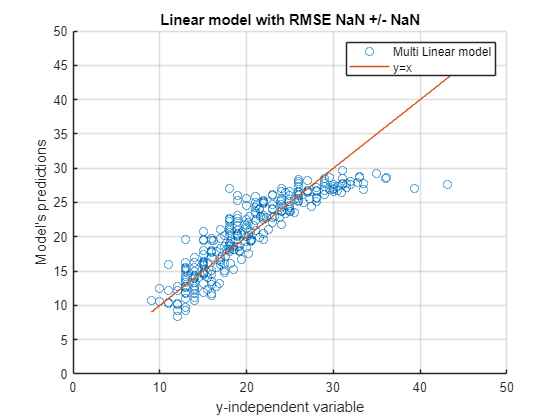

x_line = min(y):max(y);
figure
hold on
scatter(y(1:300), y_ridge_hat, DisplayName="Multi Linear model")
plot(x_line, x_line, DisplayName="y=x")
grid on
xlabel('y-independent variable')
ylabel("Model's predictions")
legend()
title_text = sprintf("Linear model with RMSE %0.3f +/- %0.2f", error, error_std );
title(title_text);
xlim([0, 50])
ylim([0, 50])

function [error, error_std] = rmse(y, y_hat)
    error = round(sqrt(sum((y - y_hat).^2)), 3);
    error_std = round(std(y - y_hat), 3);
end